# WBR控制

## 0 准备工作

[WBR系统建模分析](matlab:open('./WBR_modeling.mlx'))

[WBR腿部五连杆机构分析](matlab:open('./WBR_leg.mlx'))

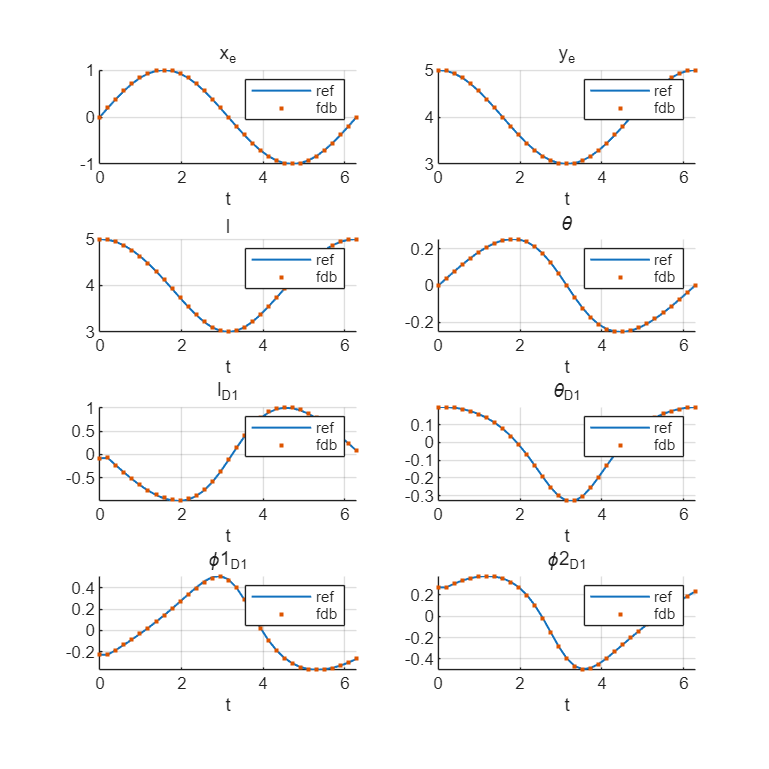

clear; clc;
run("./WBR_modeling.mlx");
run("./WBR_leg.mlx");

## 1 机器人参数

机器人质量、尺寸参数通过机械图纸测量得到，其中腿部惯量和质心位置简化近似为腿长 $l$ 的线性函数

单侧腿平面转动惯量 

$I_l\approx0.4l+0.07\ (kg\cdot m^2)$    (1.1)

腿部质心位置

$l_b\approx0.218l+0.075\ (m)$    (1.2)

$l_w=l-l_b\approx0.782l-0.075\ (m)$    (1.3)

% % robot parameters
param = struct;
param.R_w = 35e-3;
param.R_l = 153.3e-3;
param.l_wl = @(l_l)0.218*l_l+0.019;
param.l_wr = @(l_r)0.218*l_r+0.019;
param.l_bl = @(l_l)0.782*l_l-0.019;
param.l_br = @(l_r)0.782*l_r-0.019;
param.l_c = 1e-3; % -7e-3~10e-3
param.m_w = 0.08;
param.m_l = 0.51;
param.m_b = 1.919;
param.I_w = 58e-6;
param.I_ll = @(l_l)0.076*l_l-0.0015;
param.I_lr = @(l_r)0.076*l_r-0.0015;
param.I_b = 0.00435;
param.I_z = 0.032;
% leg parameters
param.l_1a = 0.0375;
param.l_1u = 0.075;
param.l_1d = 0.15;
param.l_2a = 0.0375;
param.l_2u = 0.075;
param.l_2d = 0.15;

% robot parameters(chassis)
% param = struct;
% param.R_w = 60e-3;
% param.R_l = 260e-3;
% param.l_wl = @(l_l)0.218*l_l+0.075;
% param.l_wr = @(l_r)0.218*l_r+0.075;
% param.l_bl = @(l_l)0.782*l_l-0.075;
% param.l_br = @(l_r)0.782*l_r-0.075;
% param.l_c = 1.5e-2; % -7e-3~10e-3
% param.m_w = 0.55;
% param.m_l = 2.4;
% param.m_b = 12;
% param.I_w = 624e-6;
% param.I_ll = @(l_l)0.4*l_l+0.07;
% param.I_lr = @(l_r)0.4*l_r+0.07;
% param.I_b = 0.205;
% param.I_z = 0.63;
% % leg parameters
% param.l_1a = 0.075;
% param.l_1u = 0.15;
% param.l_1d = 0.3;
% param.l_2a = 0.075;
% param.l_2u = 0.15;
% param.l_2d = 0.3;

## 2 模型实例化

将机器人的具体参数代入模型中得到实例化的模型

### 2.1 状态空间模型

% state space model instance
model = struct;
model.A = matlabFunction(subs(WBR.A, ...
  {sym("g"), ...
   WBR.R_w,WBR.R_l,WBR.l_wl,WBR.l_wr, ...
   WBR.l_bl,WBR.l_br,WBR.l_c,WBR.m_w, ...
   WBR.m_l,WBR.m_b,WBR.I_w,WBR.I_ll,WBR.I_lr, ...
   WBR.I_b,WBR.I_z}, ...
  {9.81, ...
   param.R_w,param.R_l,param.l_wl(WBR.l_l),param.l_wr(WBR.l_r), ...
   param.l_bl(WBR.l_l),param.l_br(WBR.l_r),param.l_c,param.m_w, ...
   param.m_l,param.m_b,param.I_w,param.I_ll(WBR.l_l),param.I_lr(WBR.l_r), ...
   param.I_b,param.I_z}));
model.B = matlabFunction(subs(WBR.B, ...
  {sym("g"), ...
   WBR.R_w,WBR.R_l,WBR.l_wl,WBR.l_wr, ...
   WBR.l_bl,WBR.l_br,WBR.l_c,WBR.m_w, ...
   WBR.m_l,WBR.m_b,WBR.I_w,WBR.I_ll,WBR.I_lr, ...
   WBR.I_b,WBR.I_z}, ...
  {9.81, ...
   param.R_w,param.R_l,param.l_wl(WBR.l_l),param.l_wr(WBR.l_r), ...
   param.l_bl(WBR.l_l),param.l_br(WBR.l_r),param.l_c,param.m_w, ...
   param.m_l,param.m_b,param.I_w,param.I_ll(WBR.l_l),param.I_lr(WBR.l_r), ...
   param.I_b,param.I_z}));
model.C = eye(10);

为降低计算量，通过多项式拟合得到状态方程中矩阵 A, B 关于腿长 $(l_l,l_r)$ 的近似函数。若计算资源紧张可利用矩阵 A, B 的稀疏特性进一步降低计算量。

$A(l_l,l_r)=K_{A,1}+K_{A,2}l_l+K_{A,3}l_l^2+K_{A,4}l_r+K_{A,5}l_r^2+K_{A,6}l_ll_r$    (2.1)

$B(l_l,l_r)=K_{B,1}+K_{B,2}l_l+K_{B,3}l_l^2+K_{B,4}l_r+K_{B,5}l_r^2+K_{B,6}l_ll_r$    (2.2)

% A = KA1+KA2*l_l+KA3*l_l^2+KA4*l_r+KA5*l_r^2+KA6*l_l*l_r
model.fit = struct;
[model.fit.l_l,model.fit.l_r] = meshgrid(0.15:0.025:0.4,0.15:0.025:0.4);
model.fit.l = [model.fit.l_l(:),model.fit.l_r(:)];
for i = 1:size(model.fit.l,1)
  model.fit.A_list(:,:,i) = model.A(model.fit.l(i,1),model.fit.l(i,2));
end

for i = 1:size(WBR.A,1)
  for j = 1:size(WBR.A,2)
    model.fit.Aij = model.fit.A_list(i,j,:);
    model.fit.KAij = [ones(size(model.fit.l,1),1), ...
                        model.fit.l_l(:),model.fit.l_l(:).^2, ...
                        model.fit.l_r(:),model.fit.l_r(:).^2, ...
                        model.fit.l_l(:).*model.fit.l_r(:)] ...
                      \model.fit.Aij(:);
    for k = 1:6
      model.fit.KA(i,j,k) = model.fit.KAij(k);
    end
  end
end

% figure;
% for i = 2:2:10
%   for j = 5:2:9
%     model.fit.Aij = model.fit.A_list(i,j,:);
%     model.fit.Aij = model.fit.Aij(:);
%     model.fit.KAij = model.fit.KA(i,j,:);
%     model.fit.KAij = model.fit.KAij(:);
%     model.fit.Aij_fit = [ones(size(model.fit.l,1),1), ...
%                            model.fit.l_l(:),model.fit.l_l(:).^2, ...
%                            model.fit.l_r(:),model.fit.l_r(:).^2, ...
%                            model.fit.l_l(:).*model.fit.l_r(:)] ...
%                          *model.fit.KAij;
%     model.fit.Aij_fit = reshape(model.fit.Aij_fit,size(model.fit.l_l));
%     
%     subplot(5,3,(i/2-1)*3+(j-3)/2); hold on; view(3);
%     title("A_{"+string(i)+","+string(j)+"}")
%     mesh(model.fit.l_l,model.fit.l_r,model.fit.Aij_fit);
%     plot3(model.fit.l_l(:),model.fit.l_r(:),model.fit.Aij(:),".");
%     xlabel("l_l"); ylabel("l_r");
%     set(gca,"zticklabel",[]);
%   end
% end
% set(gcf,"position",[0,0,540,800]);

fid = fopen("../doc/controller_param/KA.txt","w");
for k = 1:6
  fprintf(fid,"float KA%d[5][3] = {\r\n",k);
  for i = 2:2:10
    for j = 5:2:9
      fprintf(fid,'%.2f,',model.fit.KA(i,j,k));
    end
    fprintf(fid,"\r\n");
  end
  fprintf(fid,'};\r\n');
 end
fclose(fid);
type("../doc/controller_param/KA.txt");


float KA1[5][3] = {
-6.27,-6.27,-0.00,
-2.08,2.08,-0.00,
152.62,-12.42,-0.00,
-12.42,152.62,-0.00,
-1.29,-1.29,4.33,
};
float KA2[5][3] = {
-18.51,3.41,0.00,
-7.68,1.40,0.00,
-499.12,38.01,0.00,
-14.39,3.06,0.00,
-5.76,0.95,0.00,
};
float KA3[5][3] = {
18.29,-3.80,-0.00,
7.85,-1.61,-0.00,
574.56,-42.33,-0.00,
10.53,-2.67,-0.00,
5.86,-1.05,-0.00,
};
float KA4[5][3] = {
3.41,-18.51,0.00,
-1.40,7.68,0.00,
3.06,-14.39,0.00,
38.01,-499.12,0.00,
0.95,-5.76,0.00,
};
float KA5[5][3] = {
-3.80,18.29,0.00,
1.61,-7.85,0.00,
-2.67,10.53,0.00,
-42.33,574.56,0.00,
-1.05,5.86,0.00,
};
float KA6[5][3] = {
0.85,0.85,-0.00,
-0.55,0.55,-0.00,
-1.83,12.28,-0.00,
12.28,-1.83,-0.00,
0.24,0.24,-0.00,
};



% B = KB1+KB2*l_l+KB3*l_l^2+KB4*l_r+KB5*l_r^2+KB6*l_l*l_r
[model.fit.l_l,model.fit.l_r] = meshgrid(0.15:0.025:0.4,0.15:0.025:0.4);
model.fit.l = [model.fit.l_l(:),model.fit.l_r(:)];
for i = 1:size(model.fit.l,1)
  model.fit.B_list(:,:,i) = model.B(model.fit.l(i,1),model.fit.l(i,2));
end

for i = 1:size(WBR.B,1)
  for j = 1:size(WBR.B,2)
    model.fit.Bij = model.fit.B_list(i,j,:);
    model.fit.KBij = [ones(size(model.fit.l,1),1), ...
                        model.fit.l_l(:),model.fit.l_l(:).^2, ...
                        model.fit.l_r(:),model.fit.l_r(:).^2, ...
                        model.fit.l_l(:).*model.fit.l_r(:)] ...
                      \model.fit.Bij(:);
    for k = 1:6
      model.fit.KB(i,j,k) = model.fit.KBij(k);
    end
  end
end

% figure;
% for i = 2:2:10
%   for j = 1:4
%     model.fit.Bij = model.fit.B_list(i,j,:);
%     model.fit.Bij = model.fit.Bij(:);
%     model.fit.KBij = model.fit.KB(i,j,:);
%     model.fit.KBij = model.fit.KBij(:);
%     model.fit.Bij_fit = [ones(size(model.fit.l,1),1), ...
%                            model.fit.l_l(:),model.fit.l_l(:).^2, ...
%                            model.fit.l_r(:),model.fit.l_r(:).^2, ...
%                            model.fit.l_l(:).*model.fit.l_r(:)] ...
%                          *model.fit.KBij;
%     model.fit.Bij_fit = reshape(model.fit.Bij_fit,size(model.fit.l_l));
%     
%     subplot(5,4,(i/2-1)*4+j); hold on; view(3);
%     title("B_{"+string(i)+","+string(j)+"}")
%     mesh(model.fit.l_l,model.fit.l_r,model.fit.Bij_fit);
%     plot3(model.fit.l_l(:),model.fit.l_r(:),model.fit.Bij(:),".");
%     xlabel("l_l"); ylabel("l_r");
%   end
% end
% set(gcf,"position",[0,0,720,800]);

fid = fopen("../doc/controller_param/KB.txt","w");
for k = 1:6
  fprintf(fid,"float KB%d[5][4] = {\r\n",k);
  for i = 2:2:10
    for j = 1:4
      fprintf(fid,'%.2f,',model.fit.KB(i,j,k));
    end
    fprintf(fid,"\r\n");
  end
  fprintf(fid,'};\r\n');
 end
fclose(fid);
type("../doc/controller_param/KB.txt");


float KB1[5][4] = {
28.92,28.92,-8.15,-8.15,
-122.08,122.08,-3.08,3.08,
-350.05,-27.54,126.20,-11.27,
-27.54,-350.05,-11.27,126.20,
0.31,0.31,-231.70,-231.70,
};
float KB2[5][4] = {
-6.69,7.09,25.12,1.81,
-2.27,2.90,10.01,0.74,
1385.31,79.04,-615.48,20.35,
-16.50,6.32,28.85,1.59,
1.19,1.97,5.12,0.50,
};
float KB3[5][4] = {
10.61,-7.46,-27.93,-1.37,
3.99,-3.16,-11.53,-0.58,
-1732.72,-83.07,824.73,-15.22,
19.75,-5.28,-27.34,-1.02,
-0.92,-2.07,-5.38,-0.38,
};
float KB4[5][4] = {
7.09,-6.69,1.81,25.12,
-2.90,2.27,-0.74,-10.01,
6.32,-16.50,1.59,28.85,
79.04,1385.31,20.35,-615.48,
1.97,1.19,0.50,5.12,
};
float KB5[5][4] = {
-7.46,10.61,-1.37,-27.93,
3.16,-3.99,0.58,11.53,
-5.28,19.75,-1.02,-27.34,
-83.07,-1732.72,-15.22,824.73,
-2.07,-0.92,-0.38,-5.38,
};
float KB6[5][4] = {
0.27,0.27,-1.80,-1.80,
-0.49,0.49,0.69,-0.69,
-4.60,7.91,-2.23,-19.91,
7.91,-4.60,-19.91,-2.23,
0.07,0.07,-0.50,-0.50,
};


### 2.2 腿部模型

由于腿部连杆正运动学计算较为复杂，因此在工作空间内采用多项式拟合得到正运动学的近似结果降低计算量

$x_e(\varphi_1,\varphi_2)=K_{xe,1}+K_{xe,2}\varphi_1+K_{xe,3}\varphi_2+K_{xe,4}\varphi_1^2+K_{xe,5}\varphi_2^2+K_{xe,6}\varphi_1\varphi_2$    (2.3)

$y_e(\varphi_1,\varphi_2)=K_{ye,1}+K_{ye,2}\varphi_1+K_{ye,3}\varphi_2+K_{ye,4}\varphi_1^2+K_{ye,5}\varphi_2^2+K_{ye,6}\varphi_1\varphi_2$    (2.4)

% leg model instance
leg_model = struct;
leg_model.ikine = matlabFunction(subs([leg.ikine.phi_1;leg.ikine.phi_2], ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {param.l_1a,param.l_1u,param.l_1d, ...
                     param.l_2a,param.l_2u,param.l_2d}));
leg_model.xi = matlabFunction(subs(leg.fkine.xi, ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {param.l_1a,param.l_1u,param.l_1d, ...
                     param.l_2a,param.l_2u,param.l_2d}));
leg_model.yi = matlabFunction(subs(leg.fkine.yi, ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {param.l_1a,param.l_1u,param.l_1d, ...
                     param.l_2a,param.l_2u,param.l_2d}));
leg_model.xe = matlabFunction(subs(leg.fkine.x_e, ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {param.l_1a,param.l_1u,param.l_1d, ...
                     param.l_2a,param.l_2u,param.l_2d}));
leg_model.ye = matlabFunction(subs(leg.fkine.y_e, ...
                    {sym("l_1_a"),sym("l_1_u"),sym("l_1_d"), ...
                     sym("l_2_a"),sym("l_2_u"),sym("l_2_d")}, ...
                    {param.l_1a,param.l_1u,param.l_1d, ...
                     param.l_2a,param.l_2u,param.l_2d}));

% polynomial fitting for leg forward kinematic
% xe = Kxe1+Kxe2*phi1+Kxe3*phi2+Kxe4*phi1^2+Kxe5*phi2^2+Kxe6*phi1*phi2
% ye = Kye1+Kye2*phi1+Kye3*phi2+Kye4*phi1^2+Kye5*phi2^2+Kye6*phi1*phi2
leg_model.fit = struct;
[leg_model.fit.phi1,leg_model.fit.phi2] = meshgrid((120:5:210)/180*pi, ...
                                                   (120:5:210)/180*pi);
for i = 1:size(leg_model.fit.phi1,1)
  for j = 1:size(leg_model.fit.phi1,2)
    leg_model.fit.xi = leg_model.xi(leg_model.fit.phi1(i,j), ...
                                    leg_model.fit.phi2(i,j));
    leg_model.fit.yi = leg_model.yi(leg_model.fit.phi1(i,j), ...
                                    leg_model.fit.phi2(i,j));
    leg_model.fit.xe(i,j) = leg_model.xe(leg_model.fit.xi(1), ...
                                         leg_model.fit.xi(2), ...
                                         leg_model.fit.yi(1), ...
                                         leg_model.fit.yi(2));
    leg_model.fit.ye(i,j) = leg_model.ye(leg_model.fit.xi(1), ...
                                         leg_model.fit.xi(2), ...
                                         leg_model.fit.yi(1), ...
                                         leg_model.fit.yi(2));
  end
end

leg_model.fit.A = [ones(size(leg_model.fit.phi1(:))), ...
                   leg_model.fit.phi1(:), ...
                   leg_model.fit.phi2(:), ...
                   leg_model.fit.phi1(:).^2, ...
                   leg_model.fit.phi2(:).^2, ...
                   leg_model.fit.phi1(:).*leg_model.fit.phi2(:)];
leg_model.fit.k_xe = leg_model.fit.A\leg_model.fit.xe(:);
leg_model.fit.k_ye = leg_model.fit.A\leg_model.fit.ye(:);
leg_model.fit.k_xe

ans =    -0.0000
   -0.1491
    0.1491
    0.0184
   -0.0184
   -0.0000


leg_model.fit.k_ye

ans =     0.5369
   -0.1020
   -0.1020
    0.0000
    0.0000
    0.0207



% figure;
% subplot(1,2,1); hold on; view(3); title("x_e");
% mesh(leg_model.fit.phi1,leg_model.fit.phi2,leg_model.fit.xe);
% plot3(leg_model.fit.phi1(:),leg_model.fit.phi2(:), ...
%       leg_model.fit.A*leg_model.fit.k_xe,".");
% xlabel("phi1"); ylabel("phi2");
% subplot(1,2,2); hold on; view(3); title("y_e");
% mesh(leg_model.fit.phi1,leg_model.fit.phi2,leg_model.fit.ye);
% plot3(leg_model.fit.phi1(:),leg_model.fit.phi2(:), ...
%       leg_model.fit.A*leg_model.fit.k_ye,".");
% xlabel("phi1"); ylabel("phi2");
% set(gcf,"position",[0,0,500,200]);

## 3 控制器设计

机器人控制解耦为运动控制（Locomotion Controller）和腿部控制（Leg Controller）两部分。运动控制器通过调节驱动轮转矩和腿部关节转矩使机器人保持平衡和控制机器人移动、旋转；腿部控制器通过调节腿部支持力控制腿长，使机器人保持滚转（roll）方向稳定，并起到主动悬挂的作用。

### 3.1 运动控制器（Locomotion Controller）

根据状态空间模型设计状态反馈控制器

状态反馈控制器

$\mathbf{u}=K_{4\times10}(\mathbf{x}_d-\mathbf{x})$    (3.1)

状态反馈矩阵 K 通过 Linear Quadratic Regulator (LQR) 计算得到，代价函数

$J=\int_{0}^{\infty}\left(x^TQx+u^TRu\right)dx$    (3.2)

根据 LQR 可以得到状态反馈矩阵 K

$K=R^{-1}B^TP$    (3.3)

其中 P 满足 Riccati 方程

$A^TP+PA+PBR^{-1}B^TP+Q=0$    (3.4)

式 (3.4) 中，$A,\ B$ 是关于腿长 $l$ 的函数，为了降低运算量，在工作空间内采用多项式拟合的方式得到状态反馈矩阵 K

$K(l_l,l_r)=K_{K,1}+K_{K,2}l_l+K_{K,3}l_l^2+K_{K,4}l_r+K_{K,5}l_r^2+K_{K,6}l_ll_r$    (3.5)

% locomotion controller
locomotion_controller = struct;

% LQR
% locomotion_controller.Q = diag([1.5e3,200,5e3,1,1.5e4,1,1.5e4,1,5e4,1]);
% locomotion_controller.R = diag([200,200,10,10]);

[locomotion_controller.l_l,locomotion_controller.l_r] = ...
  meshgrid(0.15:0.025:0.4,0.15:0.025:0.4);
locomotion_controller.l = [locomotion_controller.l_l(:), ...
                           locomotion_controller.l_r(:)];
for i = 1:size(locomotion_controller.l,1)
  locomotion_controller.ss = ss(model.A(locomotion_controller.l(i,1), ...
                                        locomotion_controller.l(i,2)), ...
                                model.B(locomotion_controller.l(i,1), ...
                                        locomotion_controller.l(i,2)), ...
                                model.C,0);
  % controllability
  locomotion_controller.ctrb_list(i) = rank(ctrb(locomotion_controller.ss));
  % observability
  locomotion_controller.obsv_list(i) = rank(obsv(locomotion_controller.ss));
  % state feedback matrix(LQR)
  locomotion_controller.K_list(:,:,i) = lqr(locomotion_controller.ss, ...
                                            locomotion_controller.Q, ...
                                            locomotion_controller.R);
end

% polynomial fitting for state feedback matrix K
for i = 1:size(locomotion_controller.K_list,1)
  for j = 1:size(locomotion_controller.K_list,2)
    locomotion_controller.Kij = locomotion_controller.K_list(i,j,:);
    locomotion_controller.KKij = [ones(size(locomotion_controller.l,1),1), ...
                                  locomotion_controller.l_l(:), ...
                                  locomotion_controller.l_l(:).^2, ...
                                  locomotion_controller.l_r(:), ...
                                  locomotion_controller.l_r(:).^2, ...
                                  locomotion_controller.l_l(:).* ...
                                    locomotion_controller.l_r(:)] ...
                                \locomotion_controller.Kij(:);
    for k = 1:6
      locomotion_controller.KK(i,j,k) = locomotion_controller.KKij(k);
    end
  end
end

% figure;
% for i = 1:4
%   for j = 1:10
%     locomotion_controller.Kij = locomotion_controller.K_list(i,j,:);
%     locomotion_controller.Kij = locomotion_controller.Kij(:);
%     locomotion_controller.KKij = locomotion_controller.KK(i,j,:);
%     locomotion_controller.KKij = locomotion_controller.KKij(:);
%     locomotion_controller.Kij_fit = [ones(size(locomotion_controller.l,1),1), ...
%                                      locomotion_controller.l_l(:), ...
%                                      locomotion_controller.l_l(:).^2, ...
%                                      locomotion_controller.l_r(:), ...
%                                      locomotion_controller.l_r(:).^2, ...
%                                      locomotion_controller.l_l(:).* ...
%                                         locomotion_controller.l_r(:)] ...
%                                    *locomotion_controller.KKij;
%     locomotion_controller.Kij_fit = reshape(locomotion_controller.Kij_fit, ...
%                                             size(locomotion_controller.l_l));
%     
%     subplot(4,10,(i-1)*10+j); hold on; view(3);
%     title("K_{"+string(i)+","+string(j)+"}")
%     mesh(locomotion_controller.l_l,locomotion_controller.l_r, ...
%          locomotion_controller.Kij_fit);
%     plot3(locomotion_controller.l_l(:),locomotion_controller.l_r(:), ...
%           locomotion_controller.Kij(:),".");
%     xlabel("l_l"); ylabel("l_r");
%   end
% end
% set(gcf,"position",[0,0,2000,800]);

% save KK to file
% delete("../doc/controller_param/KK.txt");
% for i = 1:6
%   writematrix(roundn(locomotion_controller.KK(:,:,i),-2), ...
%     "../doc/controller_param/KK.txt", ...
%     "WriteMode","append", ...
%     'Delimiter',',');
% end

fid = fopen("../doc/controller_param/KK.txt","w");
for k = 1:6
  fprintf(fid,"float KK%d[4][10] = {\r\n",k);
  for i = 1:4
    for j = 1:10
      fprintf(fid,'%.2f,',locomotion_controller.KK(i,j,k));
    end
    fprintf(fid,"\r\n");
  end
  fprintf(fid,'};\r\n');
 end
fclose(fid);
type("../doc/controller_param/KK.txt");


float KK1[4][10] = {
-0.19,-0.57,-0.26,-0.07,-0.99,-0.04,-0.62,-0.02,-0.56,-0.05,
-0.19,-0.57,0.26,0.07,-0.62,-0.02,-0.99,-0.04,-0.56,-0.05,
0.42,1.27,-0.49,-0.11,5.59,0.39,-1.72,0.05,-9.58,-0.34,
0.42,1.27,0.49,0.11,-1.72,0.05,5.59,0.39,-9.58,-0.34,
};
float KK2[4][10] = {
-0.25,-0.82,0.39,0.15,-6.96,-1.46,2.67,0.07,1.43,0.09,
0.21,0.59,0.32,0.13,-5.88,-1.15,3.00,0.30,0.81,0.08,
-1.42,-4.08,-0.72,-0.30,-11.85,0.17,-18.24,-1.85,-9.57,-0.57,
-0.27,-1.02,0.49,0.16,6.76,0.63,10.28,0.38,7.31,0.39,
};
float KK3[4][10] = {
0.30,0.87,-0.36,-0.12,3.52,-0.20,-1.74,0.05,-1.43,-0.07,
-0.19,-0.59,-0.35,-0.13,3.89,0.10,-3.20,-0.46,-0.61,-0.06,
1.24,3.64,0.99,0.44,8.20,-0.30,26.15,3.10,12.52,0.68,
0.36,1.22,-0.69,-0.27,1.12,0.49,-15.76,-0.93,-9.86,-0.50,
};
float KK4[4][10] = {
0.21,0.59,-0.32,-0.13,3.00,0.30,-5.88,-1.15,0.81,0.08,
-0.25,-0.82,-0.39,-0.15,2.67,0.07,-6.96,-1.46,1.43,0.09,
-0.27,-1.02,-0.49,-0.16,10.28,0.38,6.76,0.63,7.31,0.39,
-1.42,-4.08,0.72,0.30,-18.24,-1.85,-11.85,0.17,-9.57,-0.

### 3.2 腿部控制器（Leg Controller）

控制目标：调节腿部支持力控制左右腿长度，使机体保持特定高度&滚转角，并起到悬挂减震的作用

输入：机体目标滚转角(roll) & 目标腿长(平均值) $(\psi_{d},l_d)$

输出：左右腿支持力 $(F_{bl.l},F_{bl,r})$

反馈：机体滚转角 & 左右腿长度 $(\psi_b,l_l,l_r)$

控制器：单环PID控制（PD模拟弹簧阻尼系统，I消除前馈误差）+前馈（重力+侧向惯性力矩补偿）

重力补偿前馈

$F_{bl,gravity}=(\frac{1}{2}m_b+\eta_lm_l)g$    (3.6)

侧向惯性力矩补偿前馈

$F_{bl,inertial}=(\frac{1}{2}m_b+\eta_lm_l)\frac{l}{2R_l}\dot\phi\dot{s}$    (3.7）

最终左右腿支持力

$\left[\matrix{
F_{bl,l} \cr F_{bl,r}
}\right]=\left[\matrix{
1 & 1 & 1 & -1 \cr -1 & 1 & 1 & 1
}\right]\left[\matrix{
F_{\psi} \cr F_l \cr F_{bl,gravity} \cr F_{bl,inertial}
}\right]$    (3.8)

在建模过程中将腿部机构进行了简化，控制量解耦为沿腿长方向的支持力和机体-腿关节处的转矩。而实际控制中腿部的执行器为2个关节电机，因此运动控制器输出的腿部转矩和腿部控制器输出的腿部支持力需要根据腿部机构动态静力学 ([腿部机构分析式 (5.1)](matlab:open('./WBR_leg.mlx')) ) 映射到腿部的关节电机力矩。此外，由于存在机械限位，为防止电机长时间工作在堵转状态，需要对每个关节电机通过额外的非线性控制律限制角度范围。

% leg controller
leg_controller = struct;
leg_controller.psi.kp = 100;
leg_controller.psi.ki = 0;
leg_controller.psi.kd = 50;
leg_controller.l.kp = 300;
leg_controller.l.ki = 10;
leg_controller.l.kd = 150;
leg_controller.eta_l = 0.3;

## 4 simulink仿真

[WBR控制仿真](matlab:open('./WBR_control.slx'))